# Add Water Mark

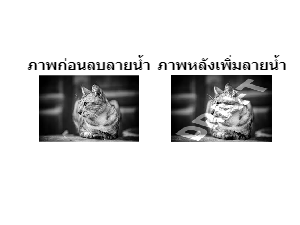

originImage = imread('cat.jpg');
watermarkImage = imread('watermark2.png');

watermarkImageResized = imresize(watermarkImage, [size(originImage, 1) size(originImage, 2)]);  %ปรับขนาด watermark_img ให้เท่ากับ originImage
alpha = 0.5; % ค่าความเข้มของลายน้ำ
watermarkedImage = im2double(originImage) + alpha * im2double(watermarkImageResized); 

figure;
subplot(1,2,1), imshow(originImage), title('ภาพก่อนลบลายน้ำ');
subplot(1,2,2), imshow(watermarkedImage), title('ภาพหลังเพิ่มลายน้ำ');


%บันทึกภาพ
imwrite(watermarkedImage, 'watermarked_image.jpg');

# Remove Water Mark with threshold

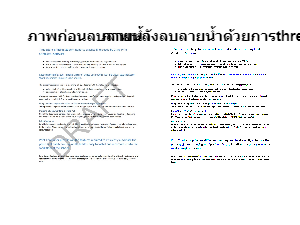

image = imread('2.jpg');

% ค่า Threshold
threshold = 180;

% ทำการลบ Watermark ออกจากภาพโดยใช้วิธีการ Thresholding
image_without_watermark = image; % สร้างภาพเปล่าขนาดเท่ากับภาพ grayscale
image_without_watermark(image > threshold) = 255; % ให้ค่าที่มากกว่า Threshold เป็นสีขาว (255)
image_without_watermark(image <= threshold) = 0; % ให้ค่าที่น้อยกว่าหรือเท่ากับ Threshold เป็นสีดำ (0)

figure;
subplot(1,2,1), imshow(image), title('ภาพก่อนลบลายน้ำ');
subplot(1,2,2), imshow(image_without_watermark), title('ภาพหลังลบลายน้ำด้วยการthreshold');

# Remove Water Mark with inpaintCoherent

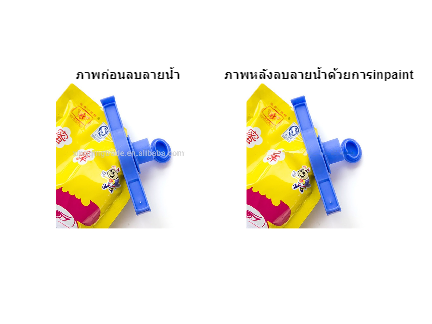

main_img = imread('image.jpeg');
watermark_img = imread('textmask.png');

watermark_img_resized = imresize(watermark_img, [size(main_img, 1), size(main_img, 2)]); %ปรับขนาด watermark_img ให้เท่ากับ main_img
watermark_gray = im2gray(watermark_img_resized); 
mask = watermark_gray ~= 0; %แปลงค่าที่ไม่เท่ากับ 0 เป็น 1
img_inpaintCoherent = inpaintCoherent(main_img, mask); 

figure;
subplot(1,2,1), imshow(main_img), title('ภาพก่อนลบลายน้ำ');
subplot(1,2,2), imshow(img_inpaintCoherent), title('ภาพหลังลบลายน้ำด้วยการinpaint');

# Remove Water Mark with medfilet

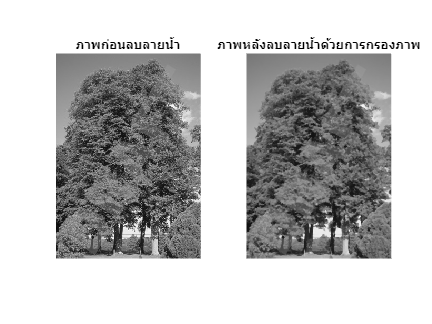

% โหลดภาพ
rgb_img = imread('5.jpg');

% แปลงภาพเป็นภาพเฉดเทา
gray_img = rgb2gray(rgb_img);

% การลบลายน้ำโดยใช้การกรองภาพ (Median Filtering)
filtered_img = medfilt2(gray_img);

% แสดงภาพเฉดเทาหลังลบลายน้ำ
figure;
subplot(1,2,1), imshow(gray_img), title('ภาพก่อนลบลายน้ำ');
subplot(1,2,2), imshow(filtered_img), title('ภาพหลังลบลายน้ำด้วยการกรองภาพ');

# Remove Water Mark with  Water Mark

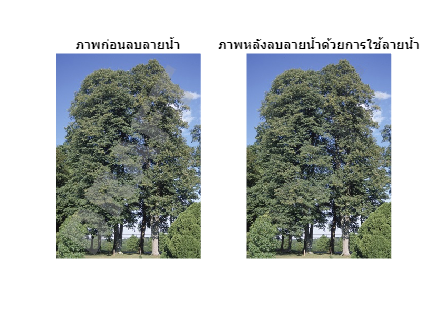

% Open-Source จาก https://www.mathworks.com/matlabcentral/answers/726273-removing-text-watermark-from-open-source-image
% เรามีรูปภาพหนึ่ง
inpict = imread('5.jpg');
% จงสมมติว่าเราทราบว่าคอมโพสิชัน (การประกอบ) คืออะไร
mask = imread('watermark.png');


opacity = 1.25; %ความเข้มสี
FG = 0.68; % สมมติว่าพื้นหน้าเป็นสีเทากลาง
% คำนวณภาพพื้นหลังเดิม
R = im2double(inpict);
mask = im2double(mask);

alpha = mask*opacity; % ค่าความเข้มของลายน้ำ
%
% คำนวณหาฺ BG ออกจาก ภาพหลัก 
BG = (R - FG.*alpha)./(1-alpha); 
% รวม BG เข้ากับภาพต้นฉบับ
% ส่วนนี้ช่วยในการกำจัดปัญหาที่เกิดขึ้นที่ขอบของ mask
BG = BG.*mask + im2double(inpict).*(1-mask);

figure;
subplot(1,2,1), imshow(inpict), title('ภาพก่อนลบลายน้ำ');
subplot(1,2,2), imshow(BG,'border','tight'), title('ภาพหลังลบลายน้ำด้วยการใช้ลายน้ำ');